# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
%Deci.Folder.Raw         = ['/Users/RobReinhart/Documents/Data/Behavioral'];              % Raw Data Folder Directory
Deci.Folder.Raw         = ['C:\Users\User\Desktop\John\AB2\Behav'];
Deci.SubjectList        = 'gui';                                                  % Cell Array of strings, 'all' or 'gui'
Deci.Step               = 5;                                              % Which Step to implement 1-TD, 2-PP, 3-Art, 4-Analysis, 5-Plot

%Deci.Folder.Version     = ['/Users/RobReinhart/Documents/Data/Processed_displace'];        % Output Folder Directory
Deci.Folder.Version     = ['C:\Users\User\Desktop\John\AB2\ProcessedData_displace'];
Deci = Checkor(Deci);

## 1. Trial Definitions

% Trial definition infomaton
Deci.DT.Type = 'Manual';                                                                        % Change if need alternative file, otherwise 'Manual' (expfunor2)
Deci.DT.Starts     = {9};                                                                       % Cell Array of Markers for Start codes.
Deci.DT.Ends       = {10};                                                                      % Cell Array of Markers for End codes.
Deci.DT.Markers    = {[21 23] [27 28] [31 32] [51 52]};                                   % Cell Array of Markers for Trial Defs
Deci.DT.Locks      = [14 30 50];                                                                % Num Array for each timelock (usually Stim, Rsp and Fdb Onset )
Deci.DT.Toi        = [-2 3];                                                                    % Time of Interest, be sure to include larger window for freq

Deci.DT.Displace.Static = [21 23];
Deci.DT.Displace.Markers = {[31 32]};
Deci.DT.Displace.Duration =2;
%Displace will add a new marker of .Num*1000 + displaced trial marker

Deci.DT.Block.Start   = {11};                                                                     % Cell Array of Markers for Block Starts
Deci.DT.Block.End     = {12};                                                                       % Cell Array of Markers for Block Starts
Deci.DT.Block.Markers = [];      

## 4. Analysis

#### General Set-Up

## 5. Plotting

#### Behavioral

%For Behavior

Deci.Analysis.Conditions    = {[21 31 51 1031] [21 31 51 1032]  [23 31 51 1031]  [23 31 51 1032] [21 31 52 1031] [21 31 52 1032] [23 31 52 1031] [23 31 52 1032]...
    [21 32 51 1031] [21 32 51 1032] [23 32 51 1031] [23 32 51 1032] [21 32 52 1031] [21 32 52 1032] [23 32 52 1031] [23 32 52 1032]};
Deci.Analysis.CondTitle     = {'Opt AB Corr nOpt' 'Opt AB Corr nWst' 'Opt CD Corr nOpt' 'Opt CD Corr nWst' ...
    'Opt AB Inc nOpt' 'Opt AB Inc nWst'  'Opt CD Inc nOpt' 'Opt CD Inc nWst' ...
    'Wst AB Corr nOpt ' 'Wst AB Corr nWst' 'Wst CD Corr nOpt' 'Wst CD Corr nWst' ...
    'Wst AB Inc nOpt' 'Wst AB Inc nWst'  'Wst CD Inc nOpt' 'Wst CD Inc Nwst' };

Deci.Plot.Behv = [];
Deci.Plot.Behv.Source = 'Definition';

Deci.Plot.Behv.Acc.Figure = [true true];
Deci.Plot.Behv.Acc.Total = {{[1 2] [5 6] [9 10] [13 14]} {[3 4] [7 8] [11 12] [15 16]}};
Deci.Plot.Behv.Acc.Subtotal = {{[1] [5] [9] [13]} {[3] [7] [11] [15]}};
Deci.Plot.Behv.Acc.Subtitle = {{'Opt AB Corr' 'Opt AB Inc' 'Wst AB Corr' 'Wst AB Inc'} {'Opt CD Corr' 'Opt CD Inc' 'Wst CD Corr' 'Wst CD Inc'} };

Deci.Plot.Behv.Acc.Block = [1:3];
Deci.Plot.Behv.Acc.Collapse.Trial =true;
Deci.Plot.Behv.Acc.Collapse.Block = true;
Deci.Plot.Behv.Acc.Collapse.Subject = true;
Deci.Plot.Behv.Acc.Collapse.Uneven = 'positional:nans';
Deci.Plot.Behv.Acc.Collapse.Movmean =  [false  false];
Deci.Plot.Behv.Acc.Collapse.MovWindow = 10;
Deci.Plot.Behv.Acc.Title = {'Reward Next Trial Opt Percent' 'Punishment Next Trial Opt Percent'};

Deci.Plot.Behv.RT.Figure = [true true];
Deci.Plot.Behv.RT.Draw = {{1 2 5 6 9 10 13 14} {3 4 7 8 11 12 15 16}};
Deci.Plot.Behv.RT.Title = {'Reward Next Trial RT' 'Punishment Next Trial RT'};
Deci.Plot.Behv.RT.Subtitle = {{'Opt AB Corr nOpt' 'Opt AB Corr nWst' 'Opt AB Inc nOpt' 'Opt AB Inc nWst' 'Wst AB Corr nOpt ' 'Wst AB Corr nWst' 'Wst AB Inc nOpt' 'Wst AB Inc nWst'} {'Opt CD Corr nOpt' 'Opt CD Corr nWst' 'Opt CD Inc nOpt' 'Opt CD Inc nWst' 'Wst CD Corr nOpt' 'Wst CD Corr nWst' 'Wst CD Inc nOpt' 'Wst CD Inc Nwst'}};
Deci.Plot.Behv.RT.Locks = [1 2];

Deci.Plot.Behv.RT.Block = [1:3];
Deci.Plot.Behv.RT.Collapse.Trial =true;
Deci.Plot.Behv.RT.Collapse.Block = true;
Deci.Plot.Behv.RT.Collapse.Subject = true;
Deci.Plot.Behv.RT.Collapse.Uneven = 'maxlength:nans';

Options

Deci.Run.Behavior = false;
Deci.Run.Extra = true;

Extra


Deci.Plot.Extra.Displace.Block = [1:3];
Deci.Plot.Extra.Displace.Collapse.Block = false;

Deci.Plot.Extra.Displace.Static = [21 23];
Deci.Plot.Extra.Displace.StaticTitle = {'Reward' 'Punishment'};
Deci.Plot.Extra.Displace.Markers = {[31 32] [51 52] [31]};
Deci.Plot.Extra.Displace.RepDim = {[1 2] [3]};
Deci.Plot.Extra.Displace.MarkersTitle = {{'O' 'W'} {'Cor' 'Inc'} {'O'}};
Deci.Plot.Extra.Displace.Duration =1;
Deci.Plot.Extra.Displace.Locks = [1 2];



Deci.Plot.Extra.List = true;
Deci.Plot.Extra.Functions = {'Deci_Displacement'};
Deci.Plot.Extra.Params = {{Deci.Plot.Extra.Displace} };

## ** 6. Run**

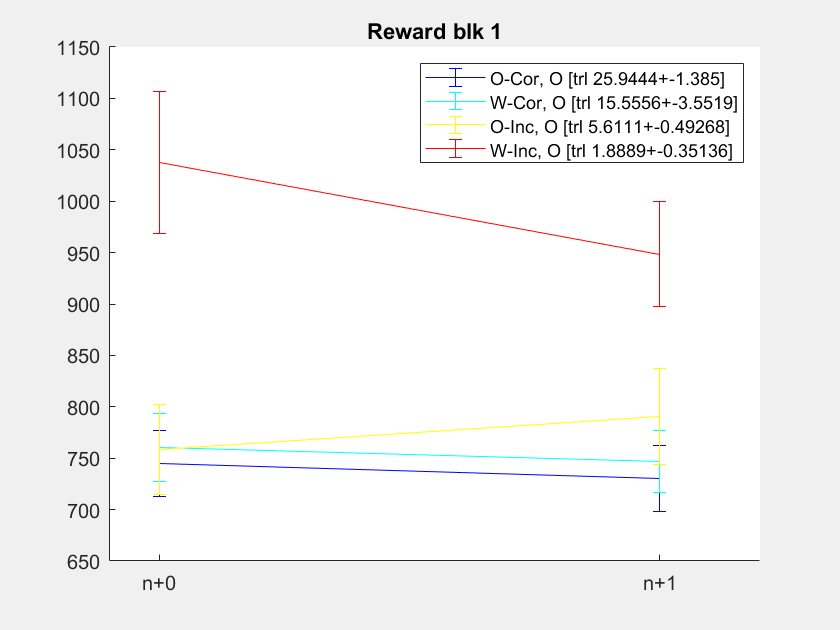

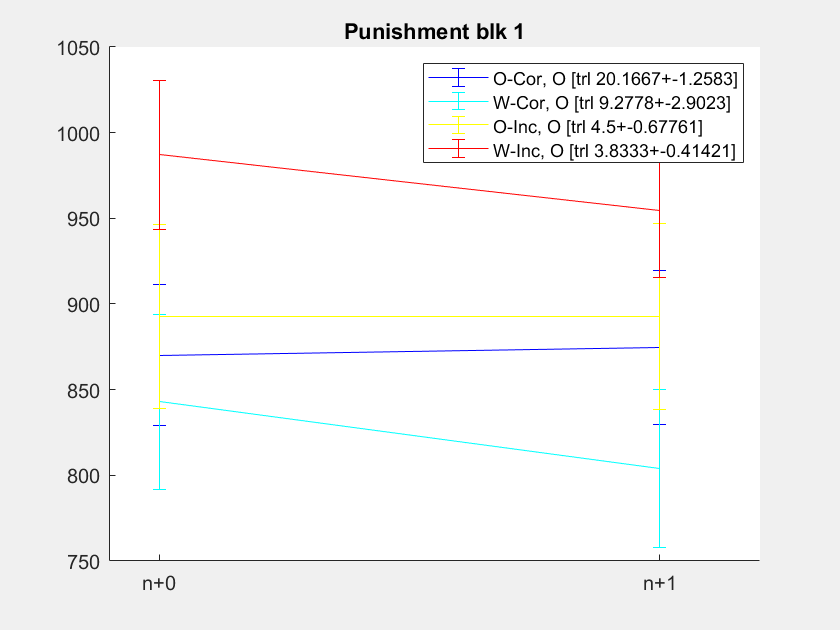

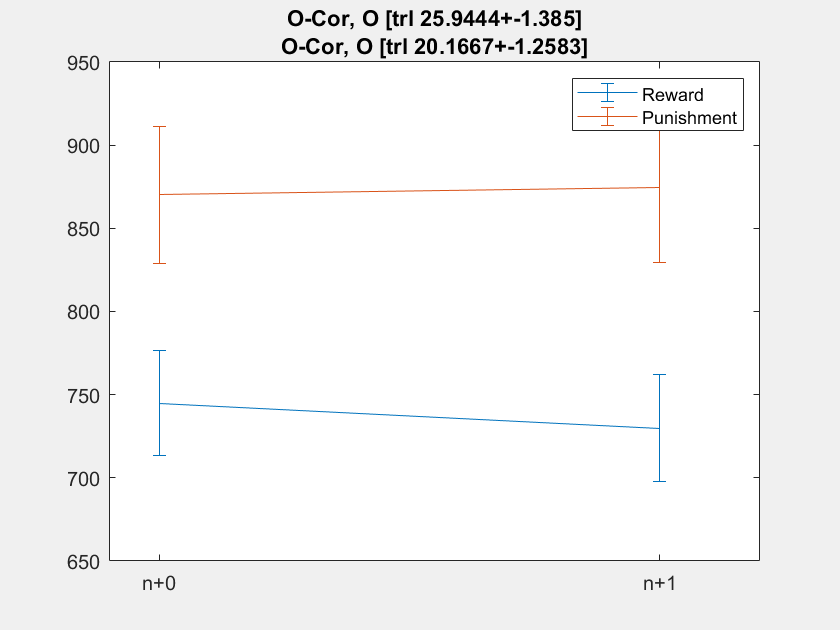

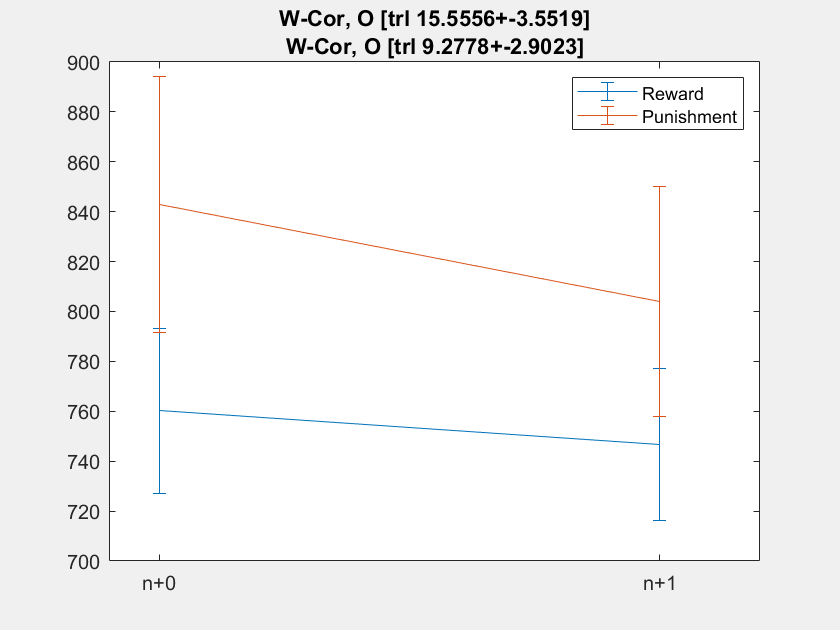

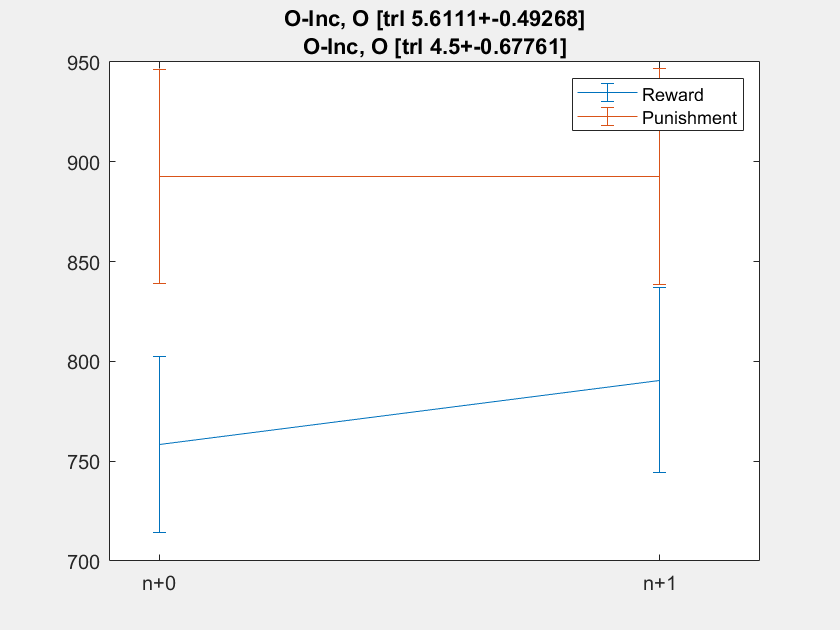

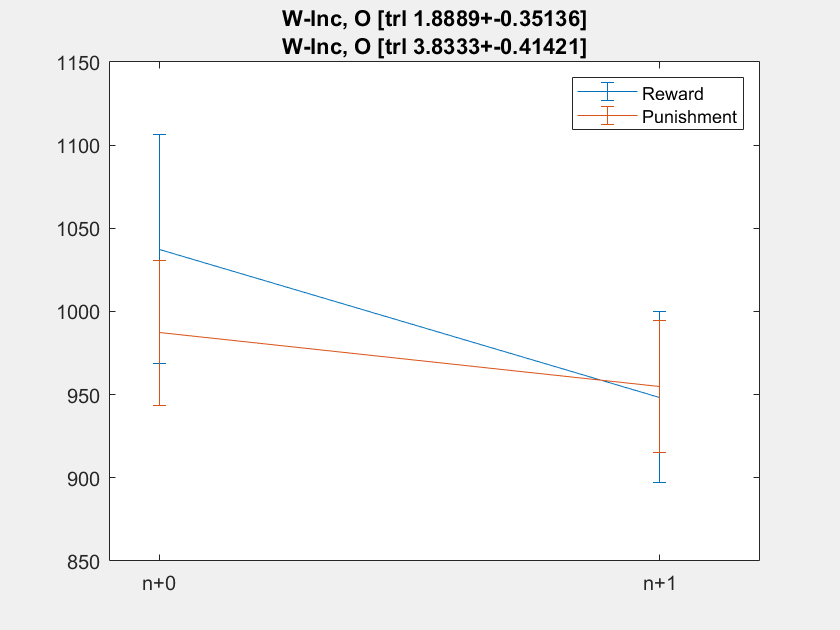

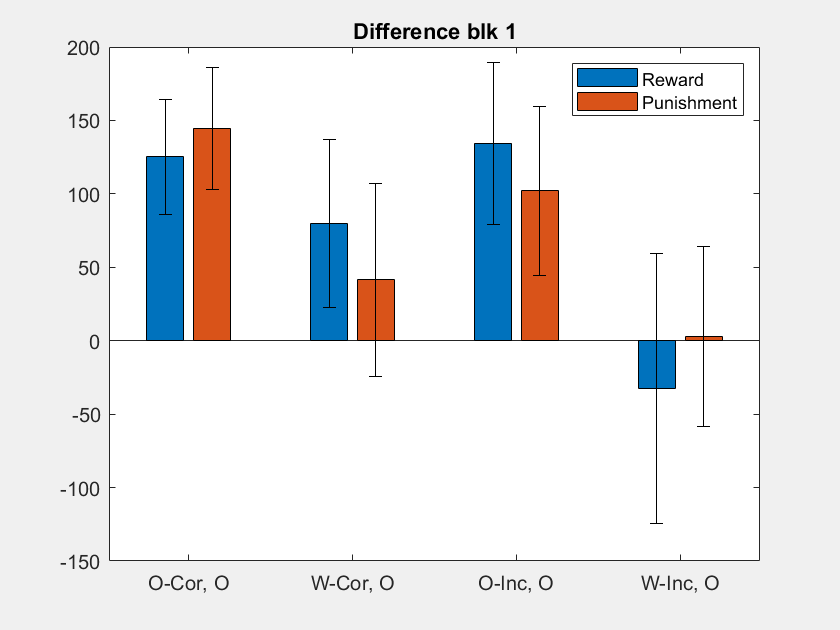

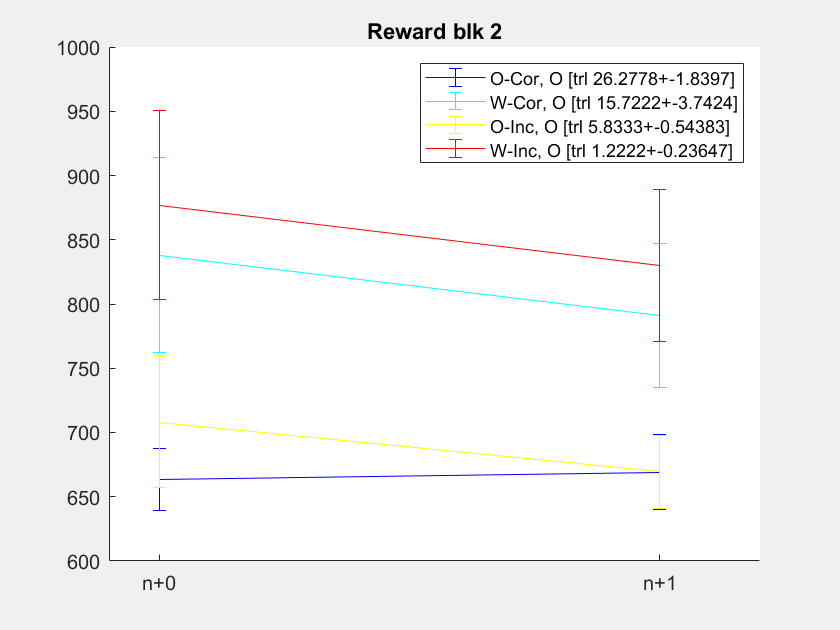

Deci_Backend(Deci);